clear
puzzle_input= ...
    ['#.#.###.#.#....#..##.#....';
    '.....#..#..#..#.#..#.....#';
    '.##.##.##.##.##..#...#...#';
    '#.#...#.#####...###.#.#.#.';
    '.#####.###.#.#.####.#####.';
    '#.#.#.##.#.##...####.#.##.';
    '##....###..#.#..#..#..###.';
    '..##....#.#...##.#.#...###';
    '#.....#.#######..##.##.#..';
    '#.###.#..###.#.#..##.....#';
    '##.#.#.##.#......#####..##';
    '#..##.#.##..###.##.###..##';
    '#..#.###...#.#...#..#.##.#';
    '.#..#.#....###.#.#..##.#.#';
    '#.##.#####..###...#.###.##';
    '#...##..#..##.##.#.##..###';
    '#.#.###.###.....####.##..#';
    '######....#.##....###.#..#';
    '..##.#.####.....###..##.#.';
    '#..#..#...#.####..######..';
    '#####.##...#.#....#....#.#';
    '.#####.##.#.#####..##.#...';
    '#..##..##.#.##.##.####..##';
    '.##..####..#..####.#######';
    '#.#..#.##.#.######....##..';
    '.#.##.##.####......#.##.##'];

entry_table = {};
i_et_col = 1;
% Visibility map from (0,0)
% 0,0 | 0,1 | 1,4 | 1,3 | ...
%     | 0,2 | 2,8 | 2,6 | ...
% ... | ... | ... | ... | ...
%
% The first element of each column occludes the next elements in the same column
% (
x_size= size(puzzle_input,1);
y_size= size(puzzle_input,2);
i_combs = 1;
x_range = -x_size:x_size;
y_range = -y_size:y_size;
% Create combination vector
combs = [];% zeros(x_size*y_size,2);
for x = x_range
    for y = y_range
        combs(i_combs,:) = [x,y];
        i_combs = i_combs + 1;
    end
end
pos_combs = combs;
[found, idx] = ismember([0,0],combs,'rows');
combs(idx,:) = []; % remove (0,0);
for x = x_range
    for y = y_range
        [found, idx] = ismember([x,y], combs, 'rows');
        if iscoprime(abs([x,y])) && found % && (x~=y)
            % Remove combination and start filling a new column
            combs(idx,:) = [];
            % create new entry and append rest of elements
            i_et_row = 1;
            entry_table{i_et_row, i_et_col} = [x,y];
            x_temp = x;
            y_temp = y;
            x_temp = x_temp + x;
            y_temp = y_temp + y;
            while (abs(x_temp) <= abs(x_size)) && (abs(y_temp) <= abs(y_size))
                i_et_row = i_et_row + 1;
                
                % Add pair if was not inserted, then remove it from the combs list
                [found, idx] = ismember([x_temp,y_temp], combs, 'rows');
                if (found)
                    entry_table{i_et_row, i_et_col} = [x_temp,y_temp];
                    combs(idx,:) = [];
                end
                
                x_temp = x_temp + x;
                y_temp = y_temp + y;
            end
            i_et_col = i_et_col + 1;
        end
    end
end
assert(isempty(combs), "Not all combinations were used");

ipa = 1;
% Part 1 - Scan all positions for asteroids
for ipx = 0:size(puzzle_input)-1
    for ipy = 0:size(puzzle_input)-1
        pos = [ipx,ipy];  % TODO loop over all positions
        n_asteroids = 0;
        for c = 1:size(entry_table,2)
            it = 1;
            found = false;
            while not(isempty(entry_table{it,c})) && not(found) && (it < size(entry_table,1))
                if isasteroid(puzzle_input, z2o(pos + entry_table{it,c}))
                    n_asteroids = n_asteroids+1;
                    found = true;
                end
                it = it +1;
            end
        end
        posasts(ipa,:) = [pos,n_asteroids];
        ipa = ipa+1;
    end
end
posasts(posasts(:,3)==max(posasts(:,3)),:) % Solution

ans =     17    13   269


## Part 2

angles_of_entry_table = [];
for it = 1:size(entry_table,2)
    coord = entry_table{1,it};
    angles_of_entry_table(it,1) = it;
    angles_of_entry_table(it,2) = angle(coord(1)+1i*coord(2));
end
[~,idx] = sort(angles_of_entry_table(:,2),'descend'); % sort just the second column
sorted_angles_of_entry_table = angles_of_entry_table(idx,:);   % sort the whole matrix using the sort indices
[idx, ~] = find(sorted_angles_of_entry_table(:,2)==pi/2,1);
ssaoet = circshift(sorted_angles_of_entry_table,-(idx-1)); % Make sure that 90deg north is the first, and move clockwise

% Start blasting!
% Get coordinate of asteroid at the same angle of the blast
% Sort first the entry table
sorted_set = entry_table(:,ssaoet(:,1));
% Now go throuh the entry table circularly (whole lines first) check and
% destroy the asteroid, repeat
puzzle_input_copy = puzzle_input;
laser_pos = z2o(posasts(posasts(:,3)==max(posasts(:,3)),1:2));
puzzle_input_copy(laser_pos(1),laser_pos(2)) = 'O';
blasted_asteroid_n = 0;
isnap = 1;
space_snapshot{isnap} = puzzle_input_copy; isnap = isnap +1;
ast200 = [];
while blasted_asteroid_n < sum(sum(puzzle_input(:,:)=='#'))-1
    r = 1;
    for it = 1:size(sorted_set,2)
        found = false;
        r = 1;
        while (not(found) && (r<=size(sorted_set,1)) && not(isempty(sorted_set{r,it})))
            xyast = laser_pos + fliplr((sorted_set{r,it})).*[-1,1];
            if isasteroid(puzzle_input_copy, xyast)
                blasted_asteroid_n = blasted_asteroid_n + 1;
                puzzle_input_copy(xyast(1),xyast(2))='+';
                space_snapshot{isnap} = puzzle_input_copy; isnap = isnap +1;
                found = true;
                if (blasted_asteroid_n==200)
                    fprintf("Solution = ");
                    disp(o2z(xyast(2))*100+o2z(xyast(1)));
                    ast200 = xyast;
                    puzzle_input_copy(xyast(1),xyast(2))='!';
                    %return
                end
            else
                r = r+1;
            end
        end
    end
end

Solution = 

   612



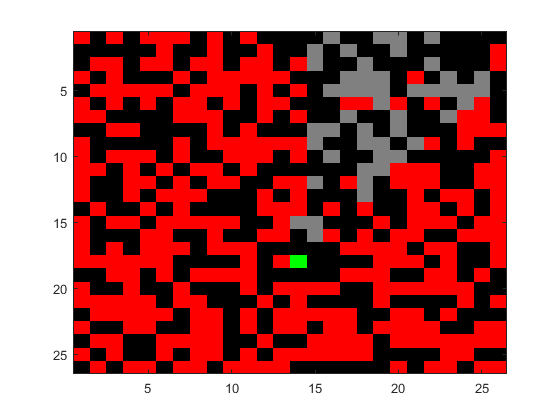

filename = 'space_blast.gif';
figure()
for i = 1:size(space_snapshot,2)
    space_mat{i} = ascii2bitmap(space_snapshot{i});
    h = image(space_mat{i});
    drawnow
    im = space_mat{i};
    [imind,cm] = rgb2ind(im,256);
    % Write to the GIF File
    if i == 1
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
end

function a2b = ascii2bitmap(space_ascii)
space_mat = zeros(size(space_ascii,2),size(space_ascii,1),3);
for c=1:size(space_ascii,2)
    for r=1:size(space_ascii,1)
        if space_ascii(r,c)=='#'
            space_mat(r,c,:) = [1,0,0];
        elseif space_ascii(r,c)=='.'
            space_mat(r,c,:) = [0,0,0];
        elseif space_ascii(r,c)=='+'
            space_mat(r,c,:) = [0.5,0.5,0.5];
        elseif space_ascii(r,c)=='O'
            space_mat(r,c,:) = [0,1,0];
        elseif space_ascii(r,c)=='!'
            space_mat(r,c,:) = [0,0,1];            
        end
    end
end
a2b = space_mat;
end

function isvisiblexy = isvisible(x,y)
% find absolute offset
end
function isa = isasteroid(puzzle_input, xy)
isa = false;
if any(xy<=0)
    return
end
if xy(1) > size(puzzle_input,1), return, end
if xy(2) > size(puzzle_input,2), return, end
if puzzle_input(xy(1), xy(2)) == '#'
    isa = true;
end
end

function y = z2o(x)
y = x+1;
end
function y = o2z(x)
y = x-1;
end
function coprime = iscoprime(x) % assuming x is an array,
GCD = x(1);             % returning greatest common divisor for the array
for i=1:size(x, 2)
    GCD = gcd(GCD, x(i));
end
coprime = GCD ==1;
end


